# Sample 8-4

## 離散コサイン変換

基底画像

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete cosine transform

Basis images

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### DCT点数

(DCT points)

nPoints = 4;

### DCT基底ベクトルの抽出

(Extraction of DCT basis vectors)

        
$$[\mathbf{C}_M]_{k,n}=\sqrt{\frac{2}{M}} \alpha_k\cos\frac{k(n+1∕2)\pi}{M},\ k,n=0,1,\cdots,M-1$$


        
$$\alpha_k=\left\{\begin{array}{ll} \frac{1}{\sqrt{2}} & k=0 \\1 & k=1,2,\cdots,M-1\end{array}\right.$$


基底ベクトル (Basis vector)

        
$$\mathbf{b}_k=\mathbf{C}_M^{-1}\mathbf{e}_k,\ k=0,1,\cdots,M-1$$


        
$$\mathbf{e}_0= (1\ 0\ \cdots\ 0)^T$$


        
$$\mathbf{e}_1= (0\ 1\ \cdots\ 0)^T$$


            
$$\vdots$$


        
$$\mathbf{e}_{M-1}= (0\ 0\ \cdots\ 1)^T$$


B = zeros(nPoints,nPoints);
for idx = 1:nPoints
    e = zeros(nPoints,1);
    e(idx) = 1;
    B(:,idx) = idct(e);
end

### 基底ベクトルの表示

(Display the basis vectors)

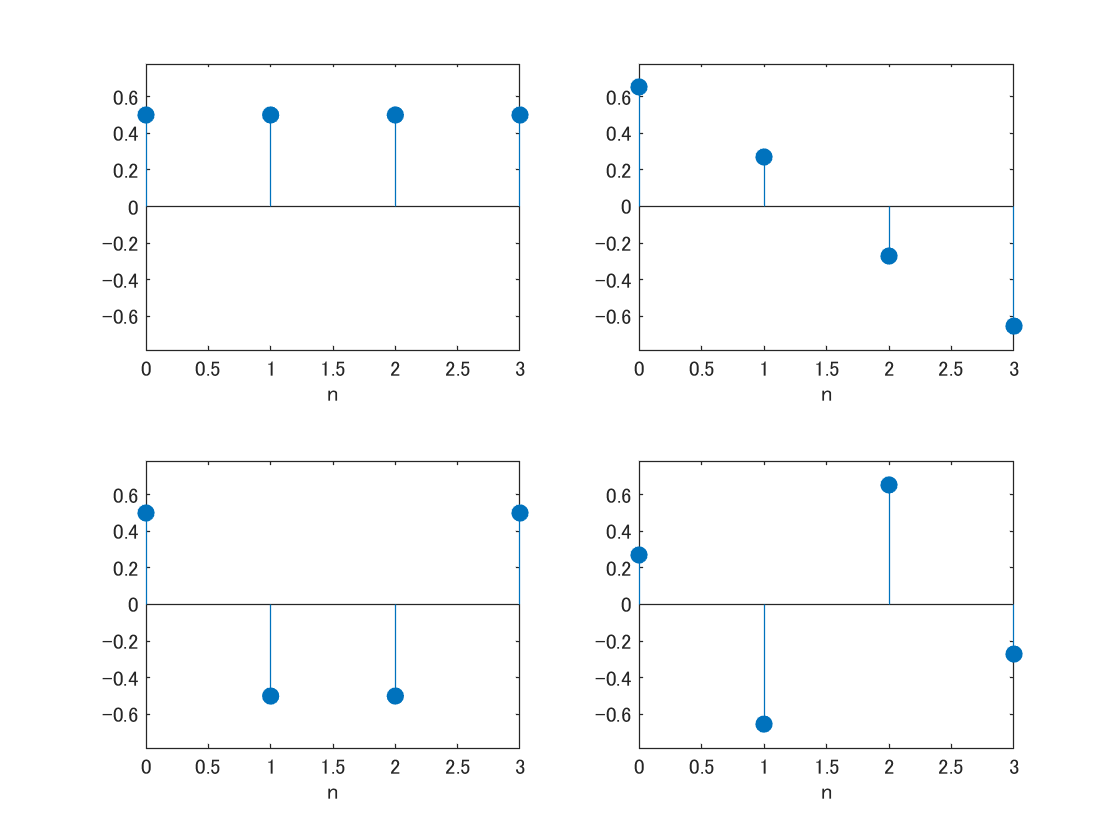

figure(1)
for idx = 1:nPoints
    subplot(ceil(nPoints/2),2,idx);
    stem(0:nPoints-1,B(:,idx),'filled');
    ax = gca;
    ax.YLim = 1.2*[min(B(:)) max(B(:))];
    xlabel('n')
end

### DCT基底画像の抽出

(Extraction of DCT basis images)

        
$$\mathbf{B}_{k,\ell}=\mathbf{C}_M^{-1}\mathbf{E}_{k,\ell}\mathbf{C}_M^{-T},\ k,\ell=0,1,\cdots,M-1$$


        
$$\mathbf{E}_{k,\ell}= \mathbf{e}_k\mathbf{e}_\ell^T$$


B = zeros(nPoints,nPoints,nPoints^2);
iBasis = 1;
for iRow=1:nPoints
    for iCol=1:nPoints
        E = zeros(nPoints,nPoints);
        E(iRow,iCol) = 1;
        B(:,:,iBasis) = idct2(E,nPoints,nPoints);
        iBasis = iBasis + 1;
    end
end

### 基底画像の表示

(Display the basis images)

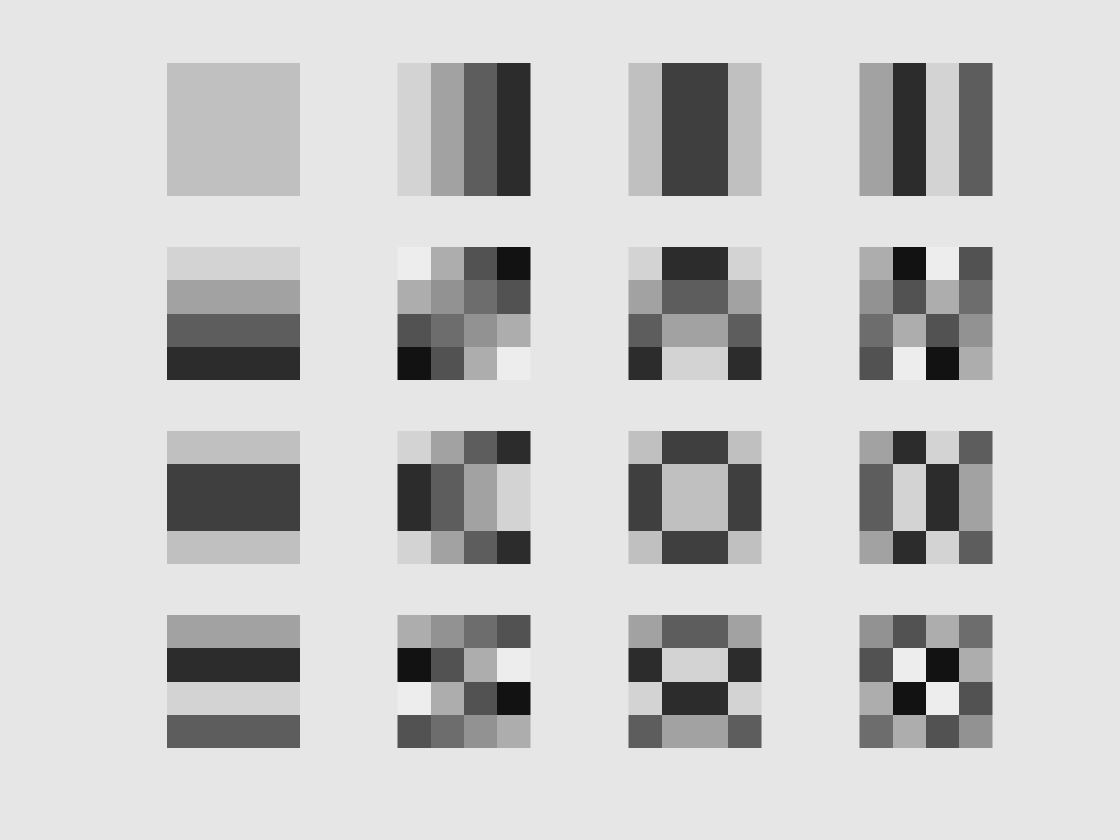

hfig2 = figure(2);
hfig2.Color = 0.9*[1 1 1];
iBasis = 1;
for iRow=1:nPoints
    for iCol=1:nPoints
        b = B(:,:,iBasis);
        subplot(nPoints,nPoints,nPoints*(iRow-1)+iCol);
        imshow(b+.5)
        iBasis = iBasis + 1;
    end
end

### 非線形近似

(Non-linear approximation)

絶対値の大きな係数のみを残して再構成 (Reconst by leaving only the coefficients with large absolute values)

% Ratio of remaining coefficients
coefRatio = 5 ;

% Read image
X = im2double(imread('cameraman.tif'));

% Block DCT 
U = blockproc(X,nPoints*[1 1],@(x) dct2(x.data));

% Non-linear approximation (Shrinking small coefficients to zero)
nCoefs = round(coefRatio/100*numel(U));
[~,I] = mink(U(:),numel(U)-nCoefs,'ComparisonMethod','abs');
U(I) = 0;
disp(['Sparsity: ' num2str(nnz(U(:))) '/' num2str(numel(U(:))) ])

Sparsity: 3277/65536


% Block IDCT
R = blockproc(U,nPoints*[1 1],@(x) idct2(x.data));

### 非線形近似の結果表示

(Display non-linear approximatiom result)

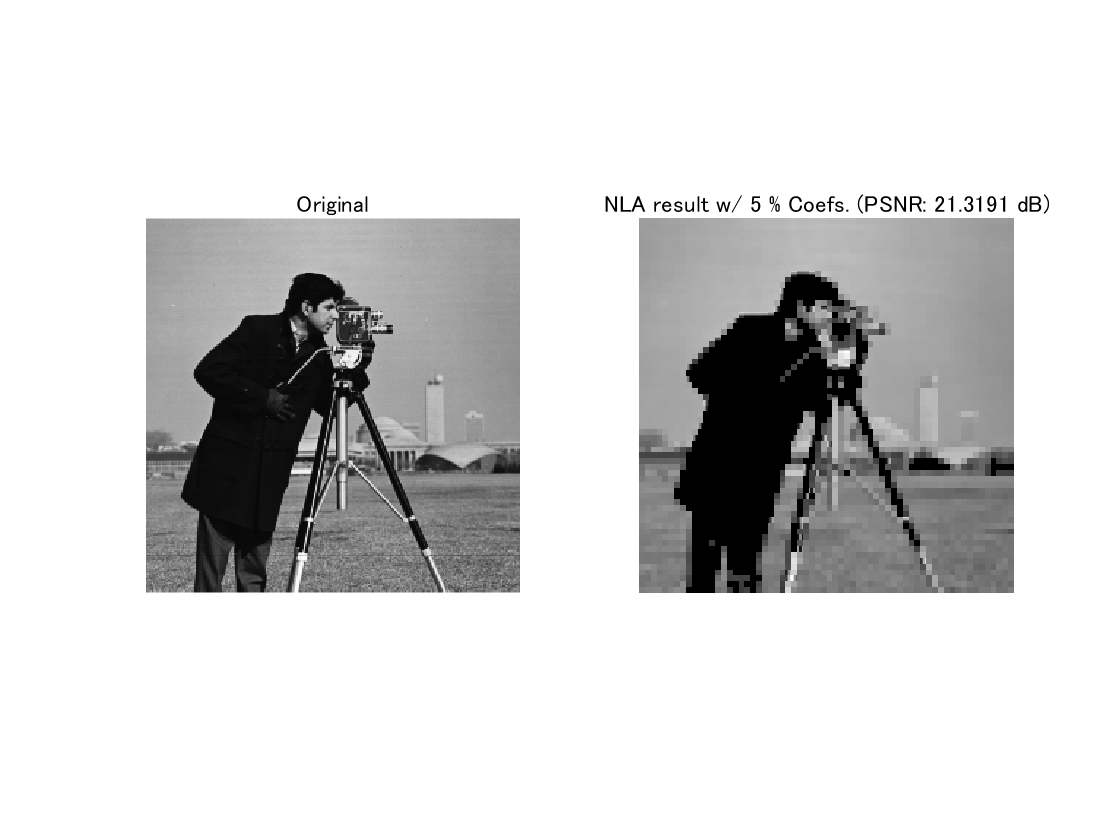

figure(3)
subplot(1,2,1)
imshow(X)
title('Original')
subplot(1,2,2)
imshow(R)
title(['NLA result w/ ' num2str(coefRatio) ' % Coefs. (PSNR: ' num2str(psnr(X,R)) ' dB)'])

© Copyright, Shogo MURAMATSU, All rights reserved.